# Lab 2

## A histogram calculation

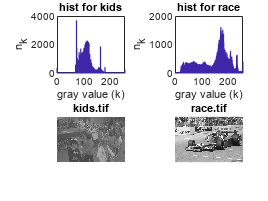

%1
clc, clear all
%reading the file
kids=imread("kids.tif");
race=imread("race.tif");

%getting the mean of the photos (ממוצע-בהירות)
kids_mean= mean(kids);
race_mean= mean(race);

%getting the standard deviation (נגידויות- שונות)
kids_std = std(double(kids));
race_std = std(double(race));

%2+3
fi=figure();
%turning the photos into vectors.
kids_vec=kids(:);
race_vec=race(:);

%plotting
subplot(2,2,1);
hist(kids_vec, 0:255);
title("hist for kids");
xlabel("gray value (k)");
ylabel("n_k");
subplot(2,2,2);
hist(race_vec, 0:255);
title("hist for race");
xlabel("gray value (k)");
ylabel("n_k");
subplot(2,2,3);
imshow(kids);
title("kids.tif");
subplot(2,2,4);
imshow(race);
title("race.tif");
saveas(fi,"PartA_result",'jpg');

## B contrast streching

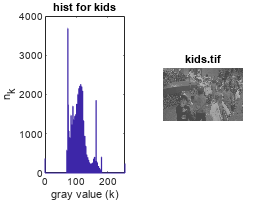

%1+2
fi=figure();
subplot(1,2,1);
hist(kids_vec, 0:255);
title("hist for kids");
xlabel("gray value (k)");
ylabel("n_k");
subplot(1,2,2);
imshow(kids);
title("kids.tif");
saveas(fi,"PartB_2",'jpg');

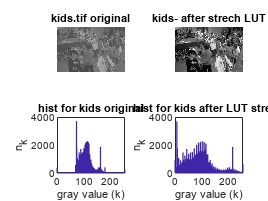

%3+4
fi=figure();
out=stretch_LUT(kids,70,180); %minimum and maximum- T1=70, T2=180
subplot(2,2,1);
imshow(kids);
title("kids.tif original");
subplot(2,2,2);
imshow(out);
title("kids- after strech LUT");
subplot(2,2,3);
hist(kids_vec, 0:255);
title("hist for kids original");
xlabel("gray value (k)");
ylabel("n_k");
subplot(2,2,4);
hist(out(:), 0:255);
title("hist for kids after LUT strech");
xlabel("gray value (k)");
ylabel("n_k");
saveas(fi,"PartB_3+4",'jpg');

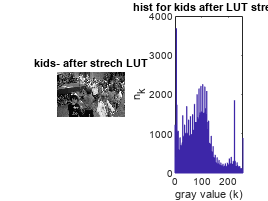


%5 after lut is better

%6 try to find T1 and T2 automaticly
%6.1- using std and mean??
%6.2 only 98% of the values will get streched.
%normalizeing the values to be at [0,1]
kids_hist_normalized = double(hist(kids_vec, 0:255))/sum(hist(kids_vec, 0:255));
kids_cdf = cumsum(kids_hist_normalized);
T1 = find(kids_cdf>0.01,1);
T2 = find(kids_cdf<0.99,1,'last');
fi=figure();
out=stretch_LUT(kids,T1,T2); %minimum and maximum- T1=70, T2=180
subplot(1,2,1);
imshow(out);
title("kids- after strech LUT");
subplot(1,2,2);
hist(out(:), 0:255);
title("hist for kids after LUT strech");
xlabel("gray value (k)");
ylabel("n_k");
saveas(fi,"PartB_6",'jpg');

## C changing contrast and brightness

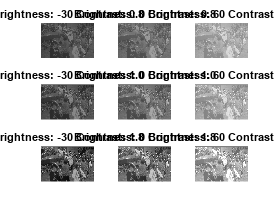

%1
clear;clc;
%2 reading the file
kids=imread("kids.tif");
%3+4+5

brightnessVec = [-30 0 60];
contrastVec = [0.8 1 1.8];
photoFig=figure();
histFig=figure();
idx=1;
for i = 1:3 %contast
    for j = 1:3 %brightness
        figure(photoFig);
        subplot(3,3,idx);
        kids_out= (double(kids)- mean(kids))*contrastVec(i) + mean(kids) + brightnessVec(j);
        imshow(uint8(kids_out));
        str = sprintf('Brightness: %d Contrast: %.1f',brightnessVec(j),contrastVec(i));
        title(str);
        
        figure(histFig);
        subplot(3,3,idx);
        hist(kids_out(:), 0:255);
        str = sprintf('Brightness: %d Contrast: %.1f',brightnessVec(j),contrastVec(i));
        title(str);
        idx=idx+1;
    end
end
saveas(photoFig,"PartC_img",'jpg');

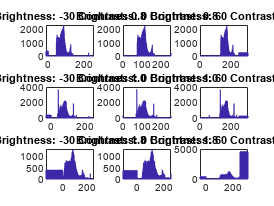

saveas(histFig,"PartC_hist",'jpg');

## D Histogram eq using LUT

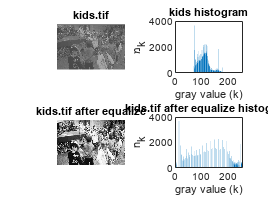

clc, clear, close all;

I=imread('kids.tif');
I_out=equalizer(I);
I_hist=hist(I(:),0:255);
I_out_hist=hist(I_out(:),0:255);

eqFigHist=figure();
figure(eqFigHist);
subplot(2,2,1);
imshow(I);
title('kids.tif');
subplot(2,2,2);
bar(I_hist);
title('kids histogram')
xlabel('gray value (k)');
ylabel('מ_k');
subplot(223);
imshow(I_out);
title('kids.tif after equalize')
subplot(224);
bar(I_out_hist);
title('kids.tif after equalize histogram')
xlabel('gray value (k)');
ylabel('n_k');
saveas(eqFigHist,"PartD",'jpg');